## Mario de Miguel Domínguez

## 1.

Las ecuaciones son, para k = 1 y ninguna de las bombas en funcionamiento.


$$\begin{array}{l}
\dot{\;h_1 } =h_2 -h_1 +h_3 -h_1 +h_4 -h_1 =-3h_1 +h_2 +h_3 +h_4 \\
\dot{\;h_2 } =h_1 -h_2 +h_4 -h_2 =h_1 -2h_2 +h_4 \\
\dot{\;h_3 } =h_1 -h_3 +h_4 -h_3 =h_1 -2h_3 +h_4 \;\\
\dot{\;h_4 } ={-K}_v h_4 +h_1 -h_4 +h_2 -h_4 +h_3 -h_4 
\end{array}$$


%Empiezo con las A. Para la válvula V cerrada, Kv = 0.
A0 = [-3 1 1 1; 1 -2 0 1; 1 0 -2 1; 1 1 1 -3]

A0 =     -3     1     1     1
     1    -2     0     1
     1     0    -2     1
     1     1     1    -3


%Y si V está abierta, Kv = k = 1
A1 = [-3 1 1 1; 1 -2 0 1; 1 0 -2 1; 1 1 1 -4]

A1 =     -3     1     1     1
     1    -2     0     1
     1     0    -2     1
     1     1     1    -4




%Cada depósito tiene una bomba que provee papilla, pero además el depósito
%1 pierde el caudal bombeado por p2, p3 y p4. Signo: el caudal que sale es negativo y lo
%que entra es positivo.
B = [1 -1 -1 -1; 0 1 0 0; 0 0 1 0; 0 0 0 1] %Para cuando p1 no está en retroceso. Si no, la primera línea sería -1 -1 -1 -1.

B =      1    -1    -1    -1
     0     1     0     0
     0     0     1     0
     0     0     0     1



%Ahora vamos con C. Para ello hay que tener en cuenta los sensores
%disponibles: depósitos 1, 3 y 4.

C = [1 0 0 0; 0 0 1 0; 0 0 0 1]

C =      1     0     0     0
     0     0     1     0
     0     0     0     1


## 2.

%Para estudiar la estabilidad miro los autovalores de las A. Para V
%cerrada.
[vA0, lA0] = eig(A0)

vA0 =     0.8165    0.2887    0.0000   -0.5000
   -0.4082    0.2887    0.7071   -0.5000
   -0.4082    0.2887   -0.7071   -0.5000
    0.0000   -0.8660    0.0000   -0.5000


lA0 =    -4.0000         0         0         0
         0   -4.0000         0         0
         0         0   -2.0000         0
         0         0         0   -0.0000


Aquí se ve que hay un autovalor 0, que corresponde a un autovalor con todas las alturas iguales. El resto de autovalores son negativos, luego el sistema evolucionará a un estado en el que las alturas de los cuatro depósitos es la misma (esto es sin accionar ninguna de las bombas de caudal).

%Y para V abierta
[vA1, lA1] = eig(A1)

vA1 =    -0.2399    0.8165    0.0000    0.5251
   -0.2399   -0.4082    0.7071    0.5251
   -0.2399   -0.4082   -0.7071    0.5251
    0.9096    0.0000    0.0000    0.4155


lA1 =    -4.7913         0         0         0
         0   -4.0000         0         0
         0         0   -2.0000         0
         0         0         0   -0.2087


En este caso se ve que todos los autovalores son negativos, luego se ve que, dejando la válvula V abierta, el sistema irá a un estado en el que los cuatro depósitos terminan vacíos.

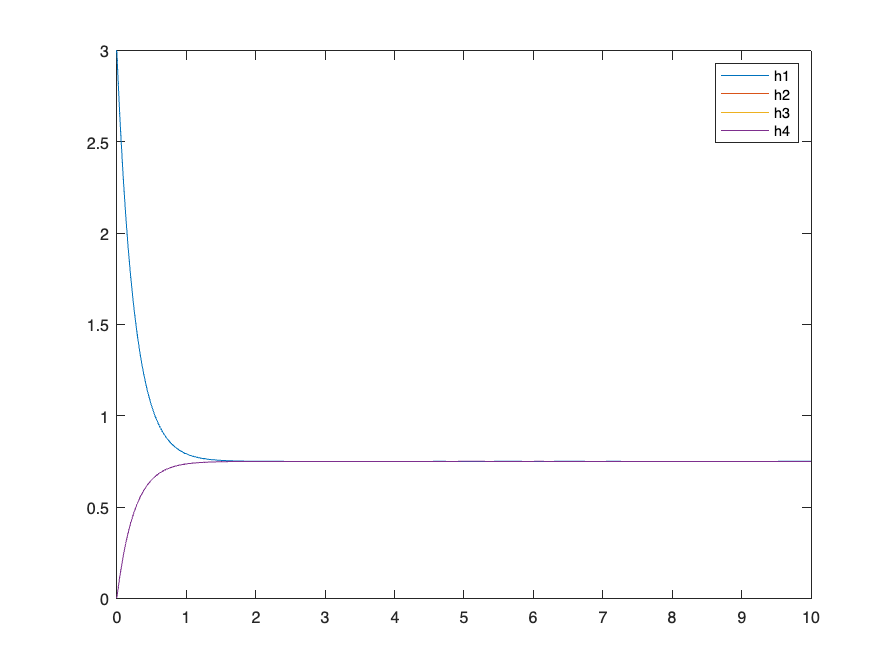

%Vamos a estudiarlo con la condición que nos dan

h0 = [3, 0, 0, 0]';
%Para la V cerrada
[t, x0] = ode45(@(t, x) A0 * x, [0 10], h0);

figure(1)
plot(t, x0)
legend("h1", "h2", "h3", "h4");

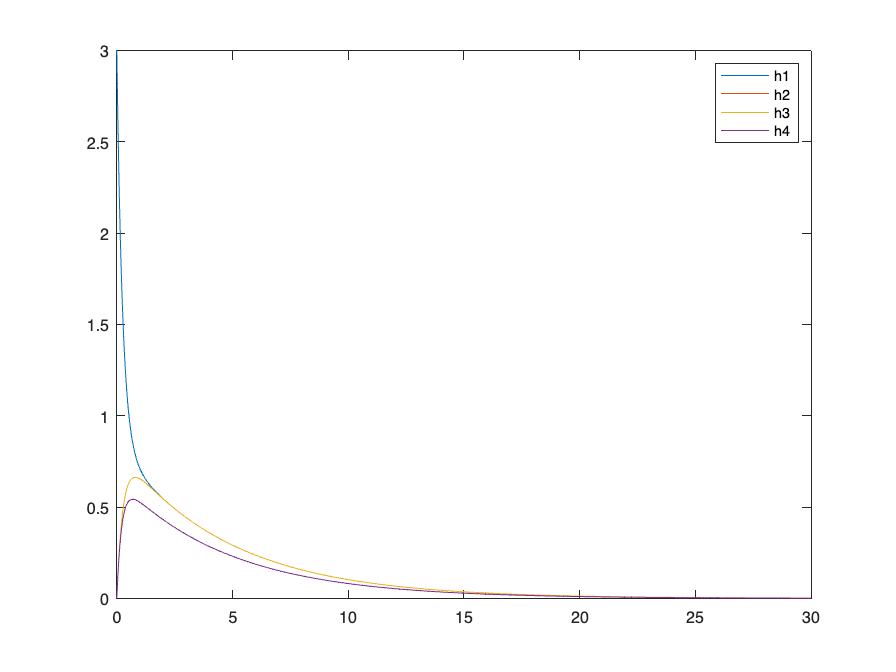

%h3 h2 y h4 son la misma curva, como es esperable (se van llenando a la
%vez). 
%Ahora para V abierta
[t, x1] = ode45(@(t, x) A1 * x, [0 30], h0);

figure(2)
plot(t, x1)
legend("h1", "h2", "h3", "h4");

Se confirma que todos los depósitos caen a 0.

## 3. 

%Compruebo que es controlable mirando el rango de la matriz de
%controlabilidad
A = A1;
rank(ctrb(A, B))

ans = 4

%Para la observabilidad miro el rango de la matriz de observabilidad
rank(obsv(A, C))

ans = 4

Tanto la matriz de observabilidad como de controlabilidad tienen rango máximo, luego el sistema es observable y controlable.

mu = 5; %El mayor autovalor posible

Q = B * B';
P = lyap(-mu * eye(4) - A, Q)

P =     2.1000   -0.4000   -0.4000   -1.4000
   -0.4000    0.4333    0.2667   -0.4000
   -0.4000    0.2667    0.4333   -0.4000
   -1.4000   -0.4000   -0.4000    2.7000


[vP, lP] = eig(P)

vP =    -0.4911    0.0000    0.6097   -0.6222
   -0.5401    0.7071   -0.4559   -0.0204
   -0.5401   -0.7071   -0.4559   -0.0204
   -0.4187         0    0.4610    0.7824


lP =     0.0262         0         0         0
         0    0.1667         0         0
         0         0    1.6395         0
         0         0         0    3.8342


Aquí ya se ve un problema y es que P no es definida positiva, luego no es una buena solución para la ecuación de Lyapunov.

K = 1/2 * B' * inv(P)

K =     4.7576    4.9697    4.9697    3.9394
    0.2121    2.1515   -0.8485    0.3030
    0.2121   -0.8485    2.1515    0.3030
   -0.8182   -0.7273   -0.7273   -0.4545


%Calculamos la L igual
Q2 = C' * C;
P2 = lyap(-mu * eye(4) - A, Q2)

P2 =     0.4857    0.0364    0.0064   -0.5143
    0.0364    0.1288    0.1405   -0.4229
    0.0064    0.1405    0.3188   -0.4629
   -0.5143   -0.4229   -0.4629    1.9000


[vP2, lP2] = eig(P2)

vP2 =     0.2063    0.4439    0.8294   -0.2691
    0.9432   -0.1361   -0.2269   -0.2008
   -0.0517    0.8288   -0.5062   -0.2327
    0.2551    0.3123    0.0655    0.9127


lP2 =     0.0147         0         0         0
         0    0.1248         0         0
         0         0    0.4312         0
         0         0         0    2.2627


Esto tampoco es una solución buena a la ecuación de Lyapunov. Tampoco es definida positiva. 

W = 1/2 * C * inv(P2);
L = W'

L =     3.0522    0.6379    2.3558
    6.1748   -1.9693    7.9619
    0.6379    3.1526    0.5024
    2.3558    0.5024    2.7952


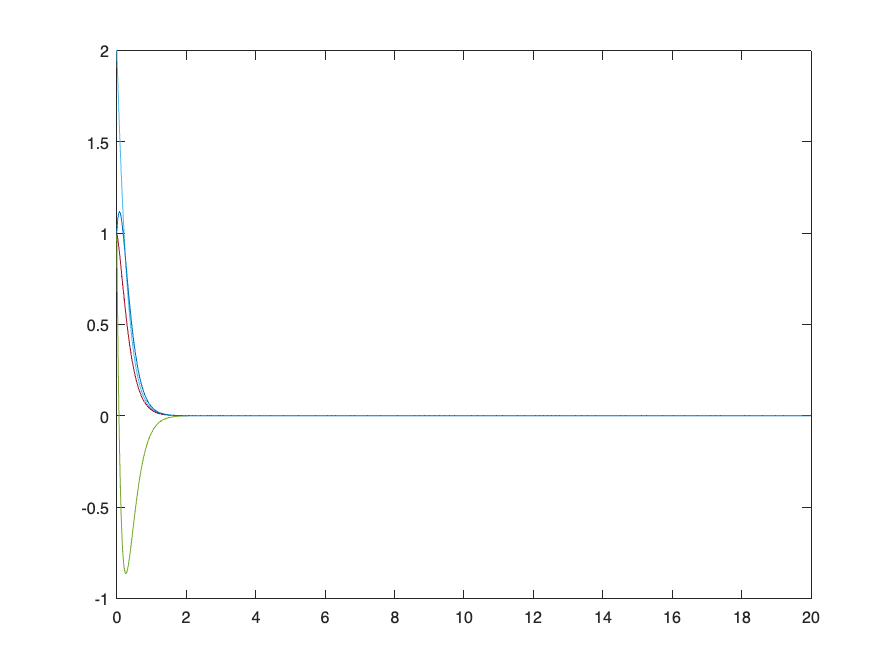

x0 = [1 2 1 1]'; %Situación inicial
xest0 = [1 2 1 1]'; %Iniciar el estimador en el mismo sitio que la situación inicial
[t, x] = ode45(@(t, x) controlador_estimador(t, x, A, B, K, L, C), [0 20], [x0; xest0]);
figure(3)
plot(t, x) 

No funciona este método para obtener bien la ganancia de la realimentación. Ni se esperaría que el estimador converja al estado ni que el estado se estabilice con las ganancias K y L obtenidas. 

Nótese que hemos elegido que todos los autovalores sean menores que -5, pero los autovalores de A, recordamos, son

lA1

lA1 =    -4.7913         0         0         0
         0   -4.0000         0         0
         0         0   -2.0000         0
         0         0         0   -0.2087


Es decir, el valor que hemos elegido no es mayor que el menor de los autovalores de la matriz A, lo que automáticamente indica que no es una buena idea poner esa mu.

## 4.

La entrada tomará forma

%La ganancia será
K = place(A, B, [-1 -2 -3 -4])

K =     1.0000    2.0000    3.0000    3.0000
    1.0000    0.0000    0.0000    1.0000
    1.0000    0.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    0.0000


%Y para el estimador
L = place(A', C', [-1 -2 -3 -4])'

L =     0.6204    1.0000    1.4492
    1.0600         0    0.9482
    1.0000   -1.0000    1.0000
    1.5425    1.0000   -0.6204


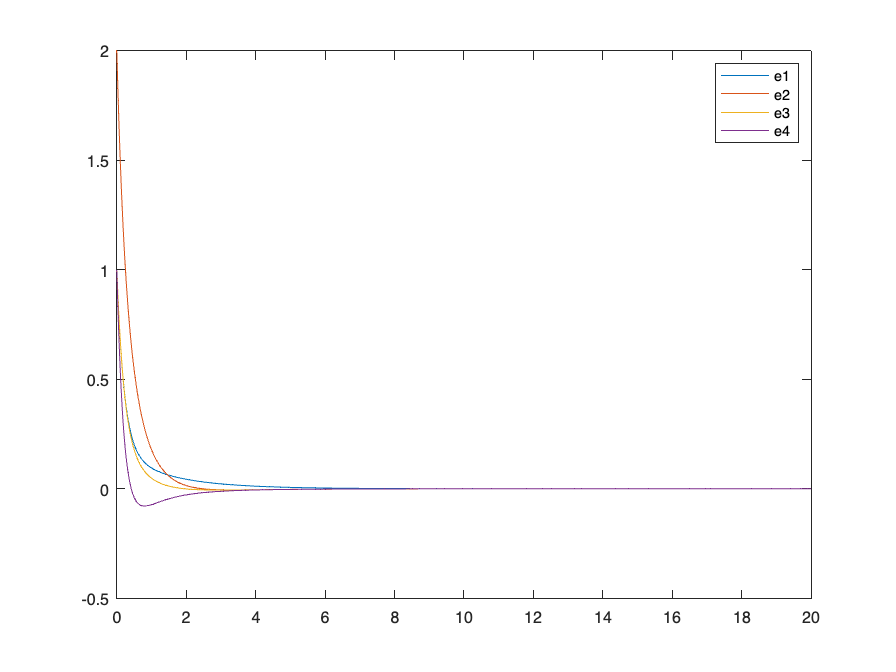

x0 = [1 2 1 1]'; %Situación inicial
xest0 = [0 0 0 0]'; %Iniciar el estimador en 0, por ejemplo.
[t, x] = ode45(@(t, x) controlador_estimador(t, x, A, B, K, L, C), [0 20], [x0; xest0]); %Definido al al final.
%Los cuatro primeros datos del vector x son del estado y los otros del
%estimador. Puedo representar el error.
figure(4)
plot(t, x(:,1:4) - x(:,5:8)) % Todos convergen a 0.
legend("e1", "e2", "e3", "e4")

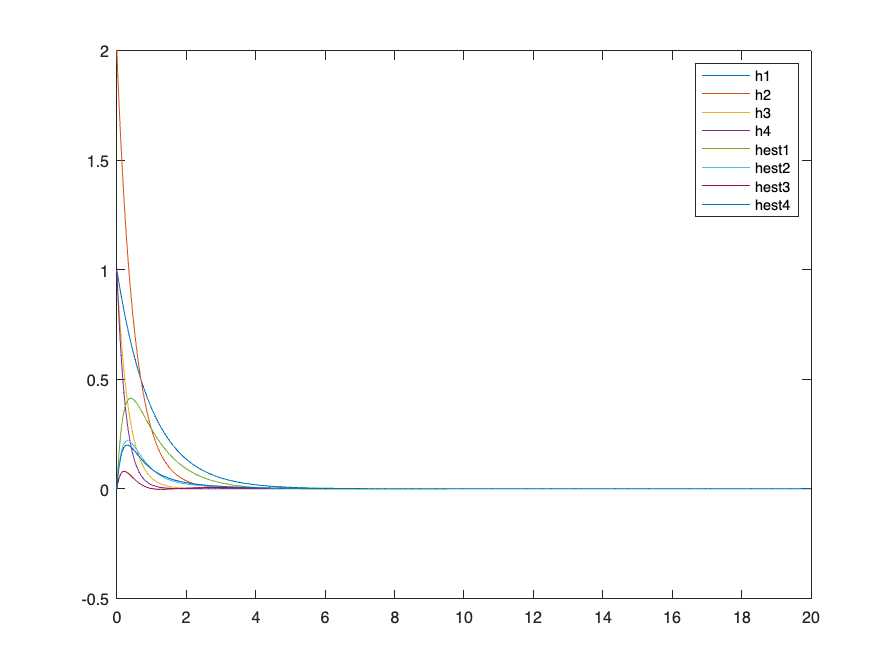

figure(5)
plot(t, x)

legend("h1", "h2", "h3", "h4", "hest1", "hest2", "hest3", "hest4");

Respecto a colocar los autovalores, cuanto más negativos sean, la señal convergerá a 0 más rápido. Es decir, colocando autovalores más cercanos a 0, se minimiza la acción del bombeo por parte de las bombas, es decir, menos caudal pasa por las tuberías y tarda más en salir todo por V. 

## 5)

%Construyo la matriz ampliada para el control integral.
hd = [1 2 3 4]'

hd =      1
     2
     3
     4


h0 = x0;
hest0 = xest0;
%Podemos usar la identidad para el c2
C2 = eye(4)

C2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Ai = [A, zeros(4); C2, zeros(4)]

Ai =     -3     1     1     1     0     0     0     0
     1    -2     0     1     0     0     0     0
     1     0    -2     1     0     0     0     0
     1     1     1    -4     0     0     0     0
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0


Bi = [B; zeros(4)];
Kt = place(Ai, Bi, [-5 -6 -7 -8 -9 -10 -11 -12]);

Ampi = [A  -B*Kt(:,1:4) -B*Kt(:,5:8);
         L*C A-B*Kt(:,1:4)-L*C -B*Kt(:,5:8);
         C2 zeros(4) zeros(4)]

Ampi =    -3.0000    1.0000    1.0000    1.0000  -20.0000   -1.0000   -1.0000   -1.0000 -132.0000   -0.0000   -0.0000   -0.0000
    1.0000   -2.0000         0    1.0000   -1.0000  -13.0000   -0.0000   -1.0000   -0.0000  -56.0000   -0.0000   -0.0000
    1.0000         0   -2.0000    1.0000   -1.0000   -0.0000  -14.0000   -1.0000   -0.0000   -0.0000  -60.0000   -0.0000
    1.0000    1.0000    1.0000   -4.0000   -1.0000   -1.0000   -1.0000  -10.0000   -0.0000   -0.0000   -0.0000  -45.0000
    0.6204         0    1.0000    1.4492  -23.6204   -0.0000   -1.0000   -1.4492 -132.0000   -0.0000   -0.0000   -0.0000
    1.0600         0         0    0.9482   -1.0600  -15.0000   -0.0000   -0.9482   -0.0000  -56.0000   -0.0000   -0.0000
    1.0000         0   -1.0000    1.0000   -1.0000   -0.0000  -15.0000   -1.0000   -0.0000   -0.0000  -60.0000   -0.0000
    1.5425         0    1.0000   -0.6204   -1.5425   -0.0000   -1.0000  -13.3796   -0.0000   -0.0000   -0.0000  -45.0000
    1.0000         0     

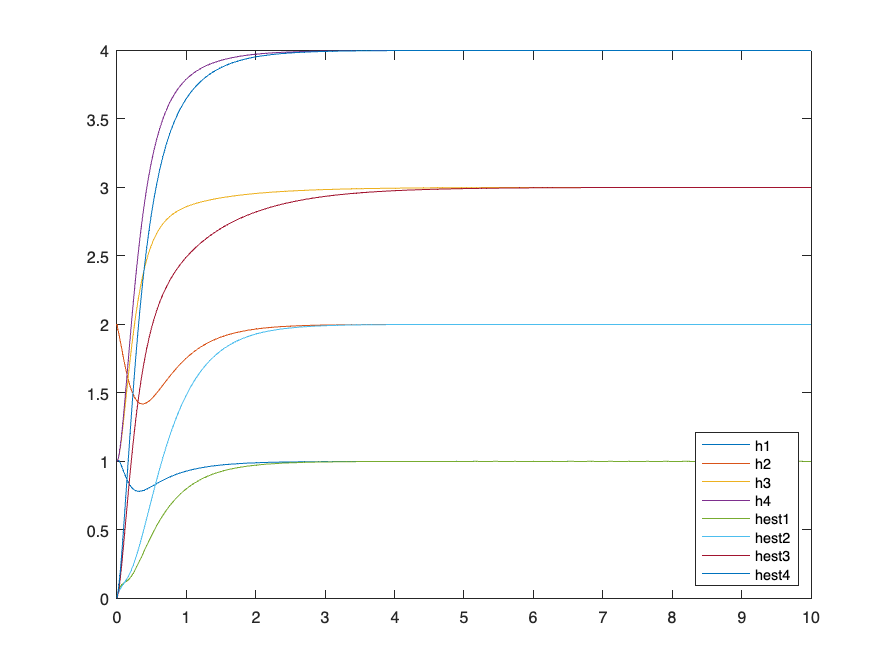

[t, xampi] = ode45(@(t, xampi) Ampi * xampi - [zeros(4), zeros(4), zeros(4); zeros(4), zeros(4), zeros(4); zeros(4), zeros(4), eye(4)] * [zeros(8, 1); hd], [0 10], [h0; hest0; zeros(4,1)]);
figure(6)
plot(t, xampi(:,1:8))
legend("h1", "h2", "h3", "h4", "hest1", "hest2", "hest3", "hest4", "Location", "southeast");

## 6)

%Miro qué pasa si pierdo cada sensor que.

C1 = [1 0 0 0];
C3 = [0 0 1 0];
C4 = [0 0 0 1];
Cs1 = [zeros(1,4); C3; C4];
rank(obsv(A, Cs1))

ans = 4


Cs3 = [C1; zeros(1,4); C4]; 
rank(obsv(A, Cs3))

ans = 3


Cs4 = [C1; C3; zeros(1,4)]

Cs4 =      1     0     0     0
     0     0     1     0
     0     0     0     0


rank(obsv(A, Cs3))

ans = 3

Directamente se ve que el sistema no pierde observabilidad si solo funcionase con los sensores de los depósitos 1 y 4.

function zdot = controlador_estimador(t, z, A, B, K, L, C)
    zdot(1:4,1) = A * z(1:4,1) - B * K * z(1:4,1); %Los vectores incluyen el estado del sistema (filas 1-4) y el del estimador (5-8)
    zdot(5:8,1) = A * z(5:8,1) - B * K * z(5:8,1) - L * C * (z(5:8,1) - z(1:4,1));
end